# Sistemas LTI Tests de estabilidad.

### (Nota: algunas de las integraciones les puede llevar un rato según con que ordenador estés trabajando. Así que, paciencia.)

Vamos a llevar a cabo, varias pruebas de estabizabilidad para ello nos buscamos un sistema, expresamente no controlable. 

No controlable

#### 
$$$A_i =\pmatrix{1&0&-2 \cr
0&-2&0\cr
2&0&3}, \ B = \pmatrix{-1& 0\cr
0&0\cr
1&2}$$


Ai = [1 0 -2; 0 -2 0 ;2 0 3];
B = [-1 0;0 0;1 2]; 

#### Matriz de Controlabilidad,

Para construir la matriz de controlabilidad, se puede usar directamente en comando de matlab ctrb

Ci = ctrb(Ai,B)

Ci =     -1     0    -3    -4    -5   -16
     0     0     0     0     0     0
     1     2     1     6    -3    10


Sabemos que el sistema será controlable si $C$ tiene rango igual a la dimensión del sistema. Tampoco hace falta ir muy lejos en este caso, es suficiente fijarse en la segunda fila de $C$

ri = rank(Ci)

ri = 2

Lo que confirma que el sistema no es controlable

#### Test de Autovectores.

Un par $(A,B)$ es estabilizable si no existe ningún autovector de $A^T$, con parte real mayor o igual que cero, en el kernel de $B^T$

Calculamos entonces los autovectores y autovalores de las matrices traspuestas de ambos sistemas

[avi,li] = eig(Ai')

avi =    0.3536 - 0.6124i   0.3536 + 0.6124i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
   0.7071 + 0.0000i   0.7071 + 0.0000i   0.0000 + 0.0000i


li =    2.0000 + 1.7321i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   2.0000 - 1.7321i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.0000 + 0.0000i


De aquí podemos aprender ya muchas cosas del sistema. Para empezar es bueno recordar que los autovalores de $A$ y $A^T$ son iguales

Hay dos autovalores con parte real positiva; así que, de entrada, el sistema es inestable

Veamos ahora la controlabilidad con el test de autovalores. Podemos multiplicar $B^T$ por las matrices de autovalores que hemos obtenido:

testi = B'*avi

testi =    0.3536 + 0.6124i   0.3536 - 0.6124i   0.0000 + 0.0000i
   1.4142 + 0.0000i   1.4142 + 0.0000i   0.0000 + 0.0000i


El último autovector de $A_i^T$ da como resultado $0$ por tanto dicho autovector está en el kernel de $B^T$ y el sistema no es controlable, como ya sabíamos. Pero afortunadamente, el autovalor correspondiente tiene parte real negativa, con lo que el sistema no tiene ningun autovector de $A_i^T$, con parte real no negativa, en el kernel de $B^T$. Luego el sistema es estabilizable.

Nota importante: cuando hay autovalores repetidos, el test que acabamos de pasar, puede inducir a error, Necesitamos asegurar que NINGUN autovector de $A^T$ esta en el kernel de $B^T$. Si la multiplicidad geométrica de los autovectores de $A^T$ para un mismo autovalor es mayor que 1, habría que comprobar que ningún vector del  subespacio que definen dichos autovectores está en el kernel de $B^T$.

#### Estabilización por descomposición controlable

Un método para estabilizar el sistema es obtener una descomposición controlable.

Empleamos el comando ctrbf de matlab, este comando exige que se le pase como variables de entrada las matrices $A,B,C$. En este ejemplo $C$ nos da igual, ya que solo nos interesa estudiar la estabilizacion. Tomamos por ejemplo $C=I_{n\times n}$. Nota: para obtener la descomposición controlable,  Matlab hace un cambio de base ortonormal, 


$$TAT^T =A_d=\pmatrix{A_u& 0 \cr  A_{21}& A_c}, TB =B_d=\pmatrix{0 \cr B_c}$$


[Ad,Bd,Cd,T]= ctrbf(Ai,B,eye(3))

Ad =    -2.0000         0         0
         0    1.1056    1.5528
         0   -2.4472    2.8944


Bd =          0         0
    0.7435   -0.4595
    1.2030    1.9465


Cd =          0   -0.9732   -0.2298
   -1.0000         0         0
         0   -0.2298    0.9732


T =          0   -1.0000         0
   -0.9732         0   -0.2298
   -0.2298         0    0.9732


Si calculamos los autovalores para la matriz del sistema de la  descomposición.

lAd =eig(Ad)

lAd =    2.0000 + 1.7321i
   2.0000 - 1.7321i
  -2.0000 + 0.0000i


Coinciden con los de $A_i$ pero ahora las submatrices $Ac$ y $B_c$, forman un par controlable,

Ac = Ad(2:3,2:3)

Ac =     1.1056    1.5528
   -2.4472    2.8944


Bc = Bd(2:3,:)

Bc =     0.7435   -0.4595
    1.2030    1.9465


rc = rank(ctrb(Ac,Bc))

rc = 2

Así que podemos definir una realimentación de estados para ella, que la estabilice,

Lo hacemos mediante la ecuación de Lyapunov, 


$$(-\mu I-A)W+W(-\mu I -A)^T = -BB^T$$


por ejemplo, para $\mu = 4$

mu = 4

mu = 4

W = lyap(-mu*eye(2)-Ac,Bc*Bc')

W =     0.0841   -0.0306
   -0.0306    0.3689


Podemos ahora calcular la ganancia de nuestra realimentación:


$$K = \frac{1}{2}B^TW^{-1}$$


P = W^-1;
K = Bc'*P/2

K =     5.1681    2.0590
   -1.8274    2.4869


Añadimos la realimentación a la submatriz $A_c$ $A_{cr}$

Acr = Ac - Bc*K 

Acr =    -3.5766    1.1647
   -5.1075   -4.4234


lAcr = eig(Acr)

lAcr =   -4.0000 + 2.4019i
  -4.0000 - 2.4019i


Con lo que vemos que nuestra matriz en lazo cerrado es Kurwitz. Podemos ahora recomponer toda la matriz del sistema, cambiando $A_c$ por $A_{cr}$,

Adr = [Ad(:,1) [zeros(1,2);Acr]]

Adr =    -2.0000         0         0
         0   -3.5766    1.1647
         0   -5.1075   -4.4234


Volvemos  a la configuración del sistema original, deshaciendo el cambio de base, 

Air = T'*Adr*T

Air =    -4.5030         0   -1.1834
         0   -2.0000         0
    5.0888         0   -3.4970


lAir= eig(Air)

lAir =   -4.0000 + 2.4019i
  -4.0000 - 2.4019i
  -2.0000 + 0.0000i


Podemos ahora simular el nuevo sistema, Pero lo interesante sería poder trabajar directamente con las matrices del sistema original.,Pora ello hacemos,

 
$$A_{ír} =T^TA_{dr}T\\
A_{ir}=T^TA_{d}T- T^T\pmatrix{0& 0\cr 0& BcK}T\\
A_{ir}=A_i + T^T\pmatrix{0\cr B_c}\cdot \pmatrix{0&-K}T\\
A_{ir} = A_i  + B\cdot \pmatrix{0&-K}T$$


Así que puede considerar mi entrada realimentada como,


$$u = \pmatrix{0&-K}Tx$$


Algunas notas sobre las dimensiones de las matrices de la expresion anterior

$B(n\times k)$, donde $n$ es el número de estados del sistema y $k$ el número de entradas (esto es conocido)

$K(k\times n_c)$, donde $n_c$ es el número de estados controlables del sistema. (Recordad que $K$ sería la (matriz) ganancia obtenida para estabilizar $A_c$

$0(k\times n_u)$donde $n_u = n-n_c$ es el número de estados no controlables del sistema

$T(n\times n)$, no es mas que una matriz de cambio de base del sistema original.

Construimos la matriz $R = \pmatrix{0&-K}T$

n = size(Ai,1); %me vale cualquiera de las dos dimensiones de A
[k,nc] = size(K); %las entradas coinciden con las filas de K,los estados controlables con las columnas 
nu = n-nc;
R = [zeros(k,nu) -K]*T

R =     5.5030         0   -0.8166
   -1.2071         0   -2.8402


Ya tenemos todos los ingredientes, podemos probar en nuestro sistema a ver si realmente se estabiliza

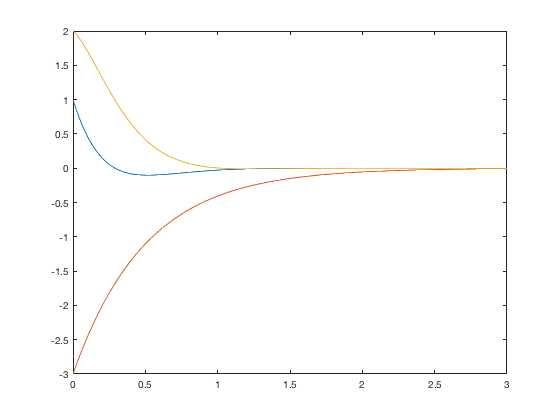

ur =@(x)U(R,x);
sys = @(t,x)sistema_lineal(t,x,ur,Ai,B);
tf = 3;
x0 = [1;-3;2]; %elegimos una condición inicial cualquiera
%opciones = odeset('maxstep',1e-5);
[t,x] = ode45(sys,[0,tf],x0);%,opciones);
figure(1)
plot(t,x)

El sistema está, por tanto, estabilizado. No era estable, pero si estabilizable.

Por supuesto, podriamos hacer los cálculos tambien construyendo un objeto sistema de matlab, pero hay que añadir unas matrices $C$, $D$, hacemos que $C =I_{3 \times 3}$ y que D sea 0

SYS = ss(Air,B, eye(3),0)


SYS =
 
  A = 
           x1      x2      x3
   x1  -4.503       0  -1.183
   x2       0      -2       0
   x3   5.089       0  -3.497
 
  B = 
       u1  u2
   x1  -1   0
   x2   0   0
   x3   1   2
 
  C = 
       x1  x2  x3
   y1   1   0   0
   y2   0   1   0
   y3   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
 
Continuous-time state-space model.



Y calculamos la respuesta a las mismas condiciones iniciales de antes con el comando initial,

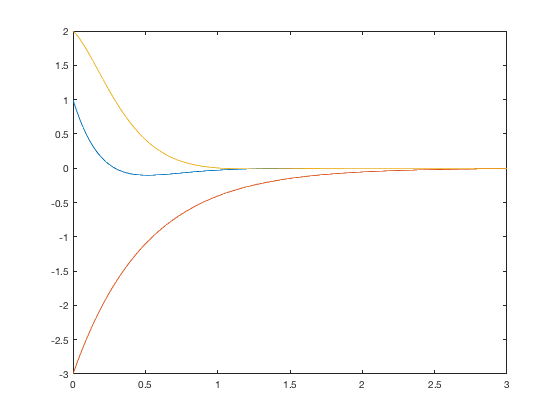

[y,t,x] = initial(SYS,x0,tf);
figure(2)
plot(t,x)

function u = U(R,x)
    %R es la matriz [0 -k]*T' de dimensión apropiada
u = R*x;
end


function xdot = sistema_lineal(t,x,U,A,B)
%modificamos el sistema lineal para ponerlo en modo realimentación
u = U(x);
xdot = A*x+B*u;
end